tstep = 200; % Current timestep

av_points = y_k_j(:,tstep,:);
av_pos = rho_i_pj_i;
colsav = any(av_points ~= -1,1);
av_points = av_points(:, colsav);
av_pos = av_pos(:,colsav);

sizeTotal = size(av_pos);
sizeTotal = sizeTotal(1,2);
av_pos = [av_pos; ones(1,sizeTotal)];

for j =  1:sizeTotal
    % Available argument for g(.)
    av_args(1:3, j) = DT * T_cv * T_op * av_pos(1:4, j);
    
    % Image Pixel values for each available point
    g_k(1:4, j) = (1/av_args(3,j)) * ([fu * av_args(1,j); fv * av_args(2,j); fu * (av_args(1,j) - b); fv * av_args(2,j)])...
        + [cu; cv; cu; cv];    
    
    % Compute camera model Jacobian
    G_cam{j,1} = [fu/av_args(3,j), 0, -((fu*av_args(1,j))/(av_args(3,j)^2));...
                    0, fv/av_args(3,j), -((fv*av_args(2,j))/(av_args(3,j)^2));...
                    fu/av_args(3,j), 0, (fu*(b - av_args(1,j)))/(av_args(3,j)^2);...
                    0, fv/av_args(3,j), -((fv*av_args(2,j))/(av_args(3,j)^2))];
       
end

Undefined operator '*' for input arguments of type 'cell'.


figure
plot3(r_i_vk_i(1,k1:k2),r_i_vk_i(2,k1:k2), r_i_vk_i(3,k1:k2))
hold on
plot3(r_k(1,:),r_k(2,:), r_k(3,:))

R_final =  R_F{1,1};
R_final = blkdiag(R_final, R_F{i,1});

% FOR TEST3
for i = 1:store-1
    %T_eps{i,1} = vec2tran(eps(i*6-5:i*6,1));
    %NewT_op{i,1} = T_kpre{i,1};
    %new_r(1:4,i) = inv(T_op{i,1}) * [0;0;0;1];
end

Undefined function or variable 'store'.

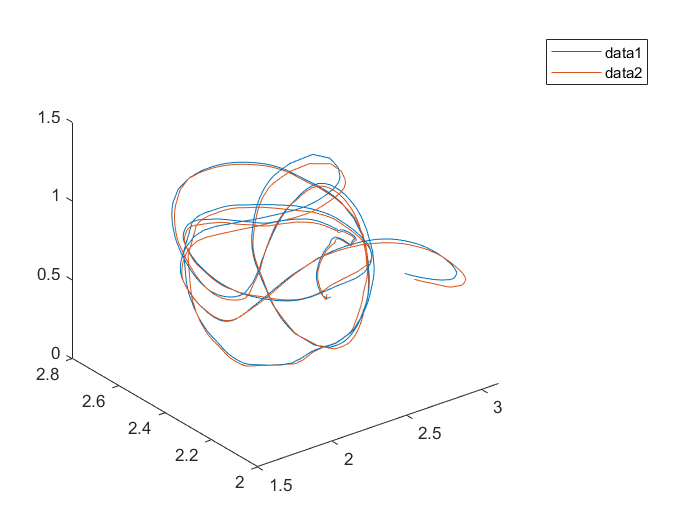

%ass = size(new_r)
figure
plot3(r_i_vk_i(1,k1:k2),r_i_vk_i(2,k1:k2), r_i_vk_i(3,k1:k2))
hold on
plot3(r_k(1,:),r_k(2,:), r_k(3,:))
legend

%hold on
%plot3(new_r(1,1:ass(2)),new_r(2,1:ass(2)), new_r(3,1:ass(2)))
%plot3(r_k(1,:),r_k(2,:), r_k(3,:))

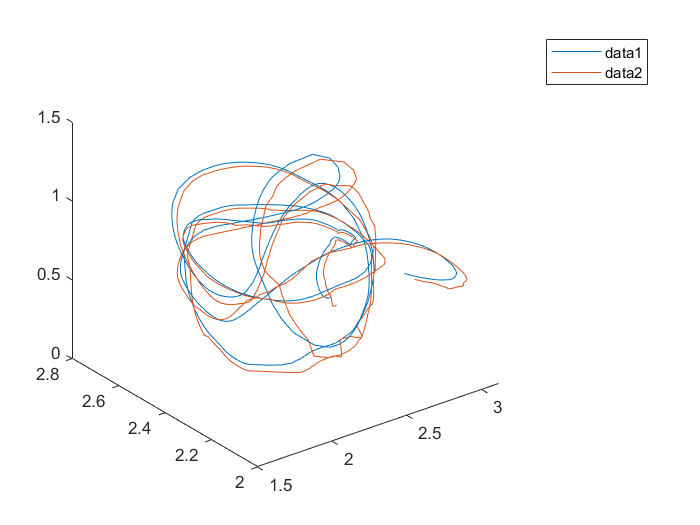

figure
plot3(r_i_vk_i(1,kinit:kend),r_i_vk_i(2,kinit:kend), r_i_vk_i(3,kinit:kend))
hold on
plot3(r_k(1,:),r_k(2,:), r_k(3,:))
legend